dx=[2 4 6 8 2  ]

dx =      2     4     6     8     2


dxi=[2 4 6 8 2  ]
dy=[81 93 91 97 95  ]

dy =     81    93    91    97    95


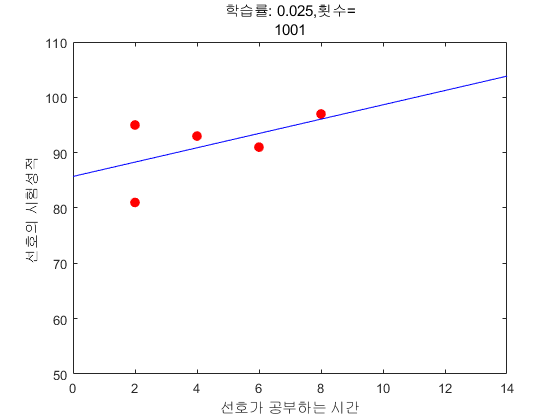

dyi=[2 4 6 8 2  ]
syms x
a=0;
b=0;
rate=0.025;

n=1001;

for num=1:n

predict=a*dx+b;
realgap=predict-dy;
adiff=2*mean(realgap.*dx);
bdiff=2*mean(realgap);

a=a-rate*adiff;
b=b-rate*bdiff;

figure(1)

plot(dx,dy,'r.','MarkerSize',25) 
axis([0 14 50 110]),title(["학습률: 0.025,횟수=",num2str(num)     ]),xlabel("선호가 공부하는 시간"),ylabel("선호의 시험성적 "),hold on

y=a*x+b;
fplot(y,'b')
hold off
drawnow
figure(2)





end